# Shortest Vector Problem (SVP)

Como se explicó en el paper

format long
f = @(x) -(0.5)*log(1-cos(x))-0.099;

%Rango de valores de x, desde 0.05rad hasta 0.35*pi (63 grados)
x_data = linspace(0.01, 0.35*pi, 20);

%Evaluamos los puntos en la funcion brindada
y_data = f(x_data);

%Tabla con los puntos utilizados a partir de la función continua

datos_tabla = table(x_data', y_data', 'VariableNames', {'x', 'c=f(x)'});

% Mostrar la tabla en la consola
disp(datos_tabla);

            x                  c=f(x)      
    __________________    _________________

                  0.01     4.85274794293806
    0.0673451278292857     2.94568729082343
     0.124690255658571      2.3301440650176
     0.182035383487857     1.95250887115039
     0.239380511317143     1.67966325321961
     0.296725639146428     1.46619221449971
     0.354070766975714     1.29106112528942
        0.411415894805     1.14278685822476
     0.468761022634285       1.014408305416
     0.526106150463571    0.901385408653342
     0.583451278292857    0.800592350690131
     0.640796406122142    0.709785179305277
     0.698141533951428    0.627298546680398
     0.755486661780714    0.551862562640942
     0.812831789609999    0.482486840338397
     0.870176917439285    0.418384164697396
     0.927522045268571    0.358918570821888
     0.984867173097856    0.303569025953637
      1.04221230092714    0.251903405912831
      1


plot(x_data, y_data, 'o')
xlabel('Eje X');
ylabel('Eje Y');
hold on;
grid on;
title('Gráfica de la función continua');

Gráfico de la función continua

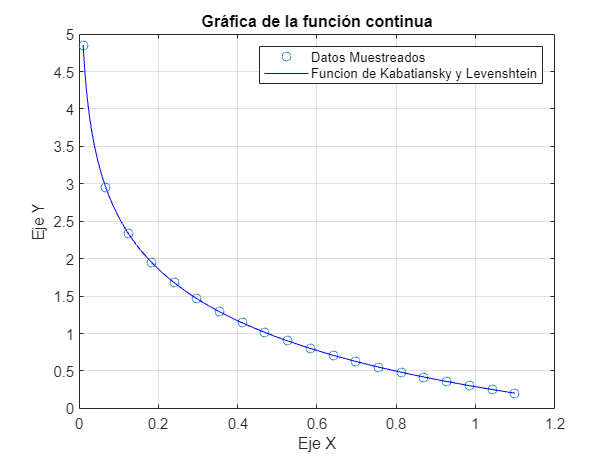

fplot(f, [0.01,0.35*pi],"-b")
legend('Datos Muestreados', 'Funcion de Kabatiansky y Levenshtein');
hold off;

Ajuste por mínimos cuadrados

% Grado del polinomio de aproximación (más alto más exacto)
n = 5;

% Coeficientes del ajuste polinomial por mínimos cuadrados
coefficients = polyfit(x_data, y_data, n);

% Mostrar los coeficientes en pantalla
disp('Coeficientes del polinomio de grado: ');

Coeficientes del polinomio de grado: 


disp(n);

     5



disp(coefficients);

   1.0e+02 *

  -0.546310807917045   1.742500807880075  -2.086483146766539   1.170451356292181  -0.326397845955118   0.049896557616066



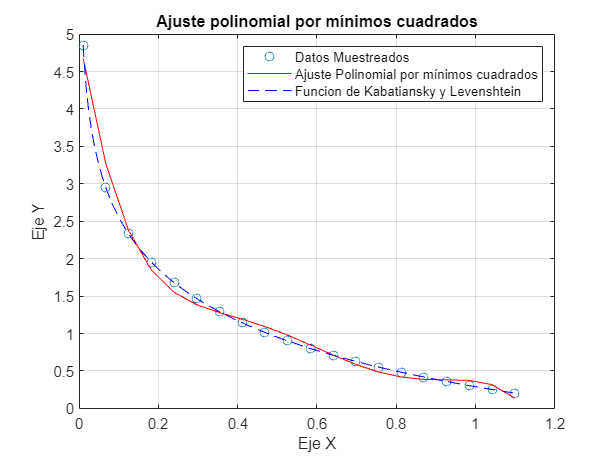



% Calcular los valores del polinomio dado por el ajuste en nuestro rango de
% valores original
y_approx = polyval(coefficients, x_data);

%Comparar el gráfico del ajuste polinomial con el de la función continua.

plot(x_data, y_data, 'o')
xlabel('Eje X');
ylabel('Eje Y');
hold on;
grid on;
title('Ajuste polinomial por mínimos cuadrados');
plot(x_data, y_approx, '-r');
fplot(f, [0.01,0.35*pi],"--b");
legend('Datos Muestreados',  "Ajuste Polinomial por mínimos cuadrados",'Funcion de Kabatiansky y Levenshtein');
hold off;

Spline natural

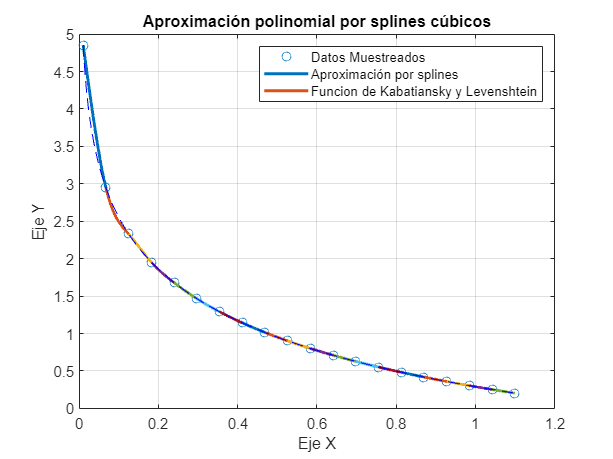

%Comparar el gráfico de la aproximacion polinomial por splines con el de la función continua.
plot(x_data, y_data, 'o')
xlabel('Eje X');
ylabel('Eje Y');
hold on;
spline = splinenatural(x_data,y_data);
fplot(f, [0.01,0.35*pi],"--b");
title('Aproximación polinomial por splines cúbicos');
legend("Datos Muestreados", "Aproximación por splines", 'Funcion de Kabatiansky y Levenshtein');
hold off;

Lagrange

% Hallamos los coeficientes (será un polinomio de grado igual al número de
% puntos brindados)
coeficientes = lagrange(x_data,y_data);
disp('Coeficientes del polinomio de grado: ');

Coeficientes del polinomio de grado: 


disp(length(x_data));

    20



disp(coeficientes);

   1.0e+09 *

   0.011834641402831  -0.120975822626624   0.572389301407353  -1.663371155847978   3.321786561518294  -4.832074417429911   5.294251983729941  -4.454559714091209   2.906876714318613  -1.474399539279658   0.578025334072431  -0.172438773884974   0.037878714811453  -0.005686874872991   0.000455903074973   0.000015245432164  -0.000009212903608   0.000001192827842  -0.000000086953714   0.000000005612022





pol_lagrange = polyval(coeficientes, x_data)

pol_lagrange =    4.852747942936968   2.945687290835262   2.330144065434600   1.952508872685371   1.679663247901538   1.466192094658787   1.291060490325831   1.142785266740232   1.014401466046778   0.901363193003847   0.800535944311886   0.709648552254678   0.627036840848731   0.551702021854610   0.482600140775443   0.420304987041936   0.365696039323155   0.323122083572290   0.300851989869558   0.315506101295619


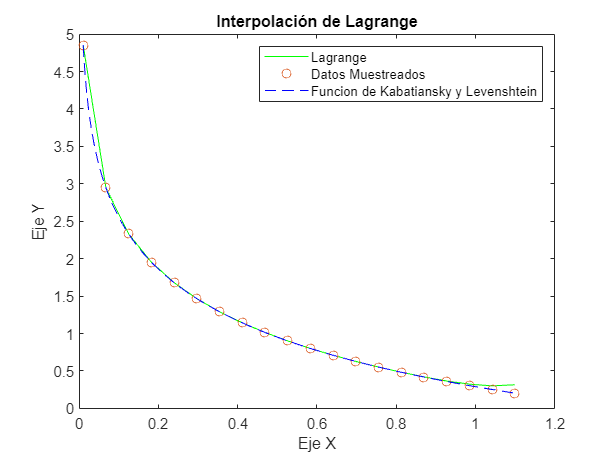

%hold off

%Comparar el gráfico de la interpolación de Lagrange con el de la función continua.
plot(x_data, pol_lagrange, "g");
hold on
plot(x_data, y_data, 'o')
xlabel('Eje X');
ylabel('Eje Y');
fplot(f, [0.01,0.35*pi],"--b");
title('Interpolación de Lagrange');
legend("Lagrange", "Datos Muestreados", 'Funcion de Kabatiansky y Levenshtein');
hold off



%pol_y = polyval(coeficientes, xx)

%plot(xx, pol_y, "g")

Función Spline

function S=splinenatural(X,Y)
    N = length(X)-1;
    H = diff(X);
    E = diff(Y)./H;
    diagprinc = 2*(H(1:N-1)+H(2:N));
    diagsupinf = H(2:N-1);
    g0 = 0; gn = 0;
    A = diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b = 6*diff(E');
    g = A\b;
    g = [g0 g' gn];
    colors = lines(length(X));
    for i = 1:N
        S(i,1) = (g(i+1)-g(i))/(6*H(i));
        S(i,2) = g(i)/2;
        S(i,3) = E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4) = Y(i);
        xx = linspace(X(i), X(i+1), 100);
        yy = S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy, 'LineWidth', 2,'Color',colors(i,:))
        hold on
    end
    grid on
    %hold off
end

Interpolación de Lagrange

function p = lagrange(x,y)
    n = length(x);
    p = zeros(1,n);

    for k = 1:n
        num = poly(x([1:k-1,k+1:n]));
        den = polyval(num,x(k));
        L = num/den;
        p = p + y(k)*L;
    end
end